[x,Fs] = audioread("a.mp3");
x = resample(x,8000,48000);

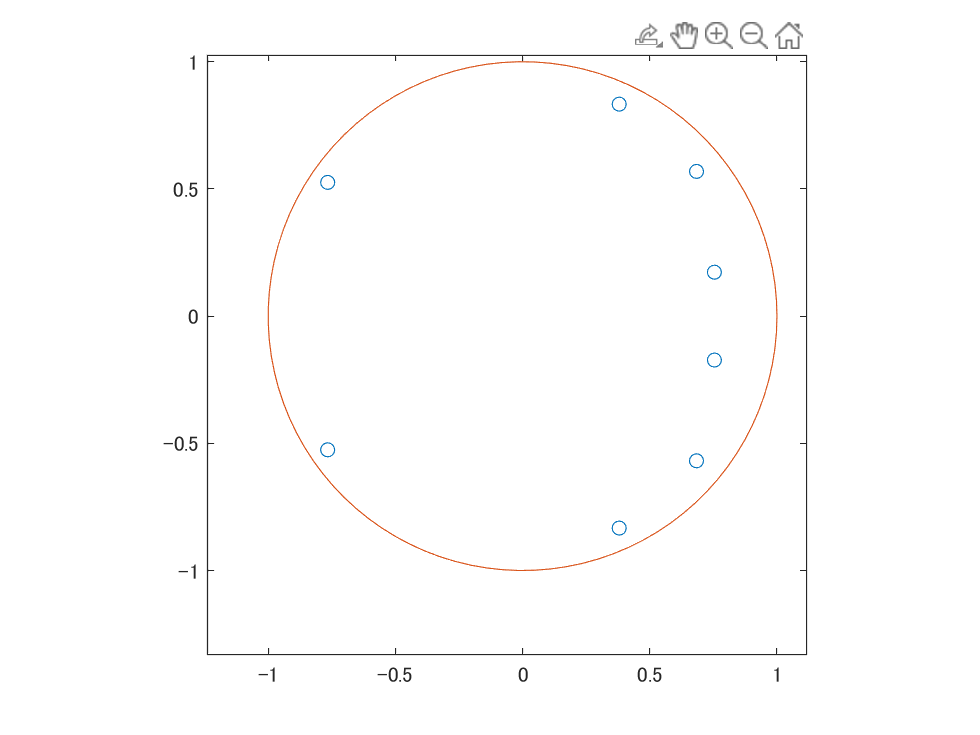

a = lpc(x,8);
[z,p,k] = tf2zpk(1,a);
plot(p,"o")
hold on
theta = linspace(0,2*pi);
plot(cos(theta),sin(theta))
hold off
axis square

p = [p([3,5]);conj(p([3,5]))];

abs(p);

[b,a] = zp2tf([],p,1);
fvtool(b,a);

fs = 8000;
TIME = 1;
t = 0:1/fs:TIME;
x = synthSaw(300,t,fs);
y = filter(b,a,x);
soundsc(y,fs)

極の振幅は0.9くらいにする